# Euler Bernoulli beam with cubic spring and damper

Generate model

clear all;
nElements = 25;
kappa = 6; % cubic spring
gamma = -0.02; % cubic damping
[M,C,K,fnl,f_0] = build_model(kappa, gamma, nElements);
n = length(M);
% Dynamical system setup 

DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',3,'Nmax',10,'notation','multiindex')

We assume periodic forcing of the form


$$\mathbf{f}^{ext}(\phi) = \mathbf{f}_0\cos(\phi)=\frac{\mathbf{f}_0}{2}e^{i\phi} 
+ \frac{\mathbf{f}_0}{2}e^{-i\phi}  $$


epsilon = 0.01;

Fourier coefficients of Forcing

kappas = [-1; 1];
coeffs = [f_0 f_0]/2;
DS.add_forcing(coeffs, kappas,epsilon);
% Linear Modal analysis and SSM setup
[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 3 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 8.839900e-04
modal damping ratio for 2 mode is 5.485350e-03
modal damping ratio for 3 mode is 1.535575e-02

 The first 6 nonzero eigenvalues are given as 
   1.0e+02 *

  -0.0001 + 0.0700i
  -0.0001 - 0.0700i
  -0.0024 + 0.4387i
  -0.0024 - 0.4387i
  -0.0189 + 1.2283i
  -0.0189 - 1.2283i



**Choose Master subspace (perform resonance analysis)**

S = SSM(DS);
set(S.Options, 'reltol', 0.5,'notation','multiindex')
masterModes = [1,2]; 
S.choose_E(masterModes);

(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     1
     8     2
     0     6
     1     7
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i

sigma_out = 304
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i

sigma_in = 304


(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     1
     8     2
     0     6
     1     7
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i

sigma_out = 304
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i

sigma_in = 304
Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation

 Second order SSM computation 

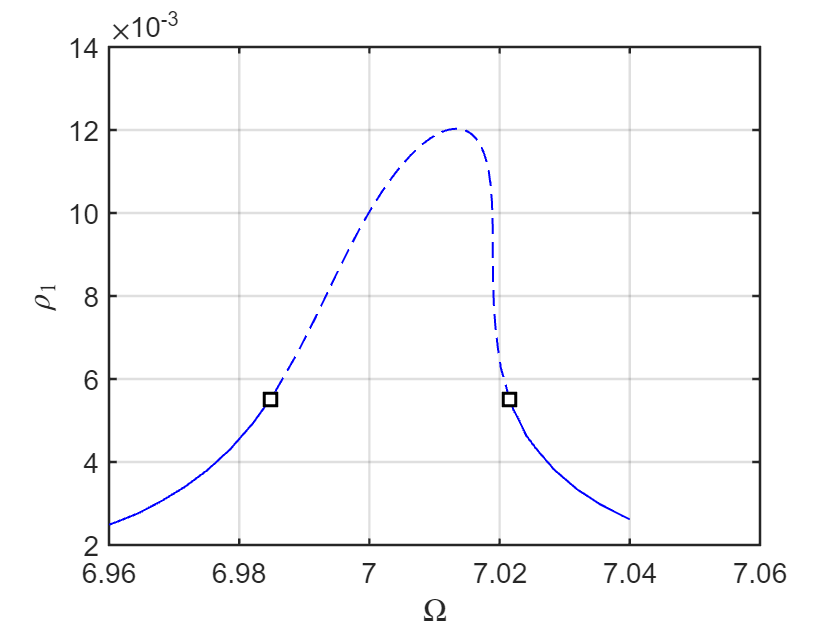

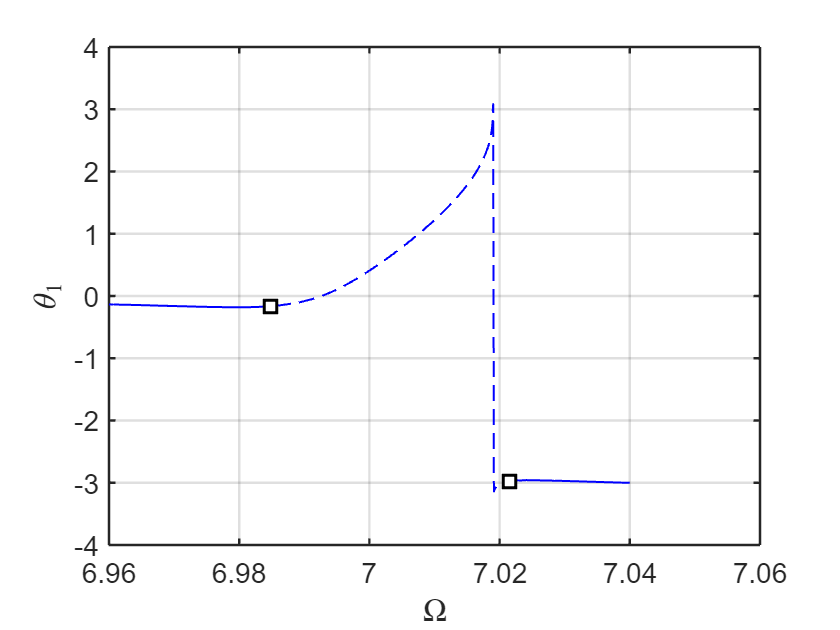

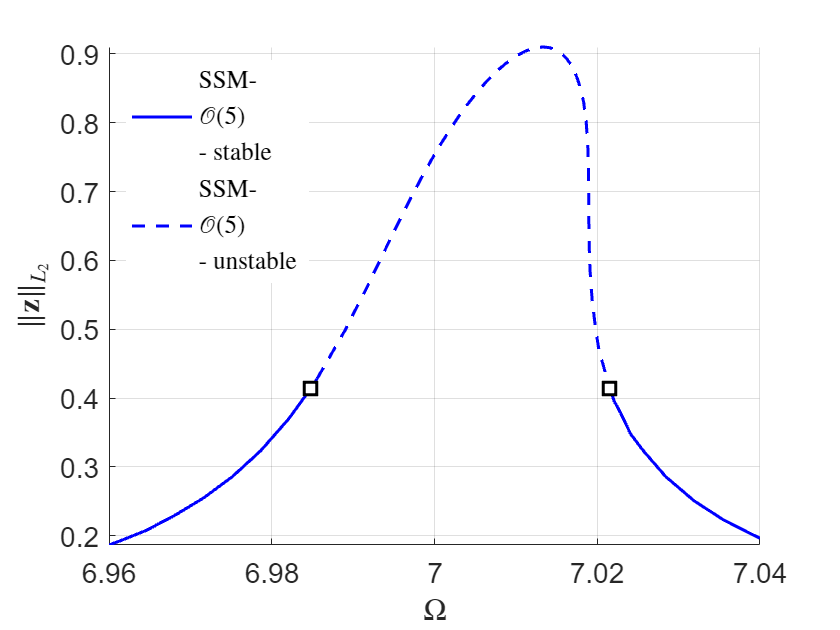

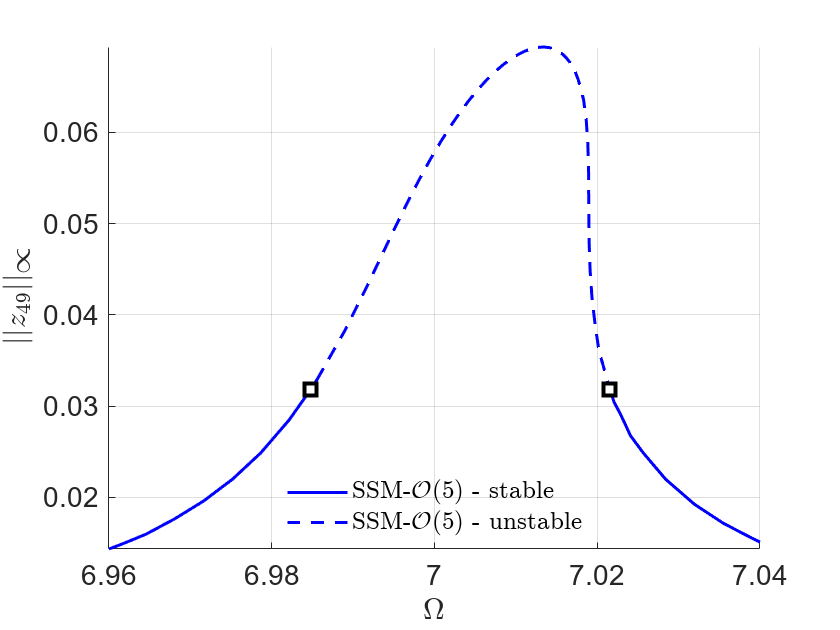

% Forced response curves using SSMs
% Obtaining *forced response curve* in reduced coordinate

order = 5; % SSM approximation order
outdof = n-1; %[n-1 n 2*n-1 2*n]; % degree of freedom at which output is displayed
freqRange = [6.96 7.04];
mFreq = 1;
% *SSM_isol2ep: continuation of equilibrium points*

set(S.contOptions, 'h0',1e-3,'h_min',1e-3,'h_max',0.005, 'PtMX', 250);  % continuation setting
set(S.FRCOptions, 'initialSolver', 'fsolve');   % solver for initial solution
set(S.FRCOptions, 'coordinates','cartesian');
set(S.Options, 'contribNonAuto',false, 'COMPtype', 'first');
startep = tic;
p0 = [6.96 epsilon]';
z0 = [1e-3 0]';
FRC1 = S.SSM_isol2ep('isol',masterModes,order,mFreq,'freq',freqRange,outdof,{p0,z0});

timings.epFRC = toc(startep);

(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     1
     8     2
     0     6
     1     7
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i

sigma_out = 304
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i

sigma_in = 304
Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation

 Second order SSM computation 

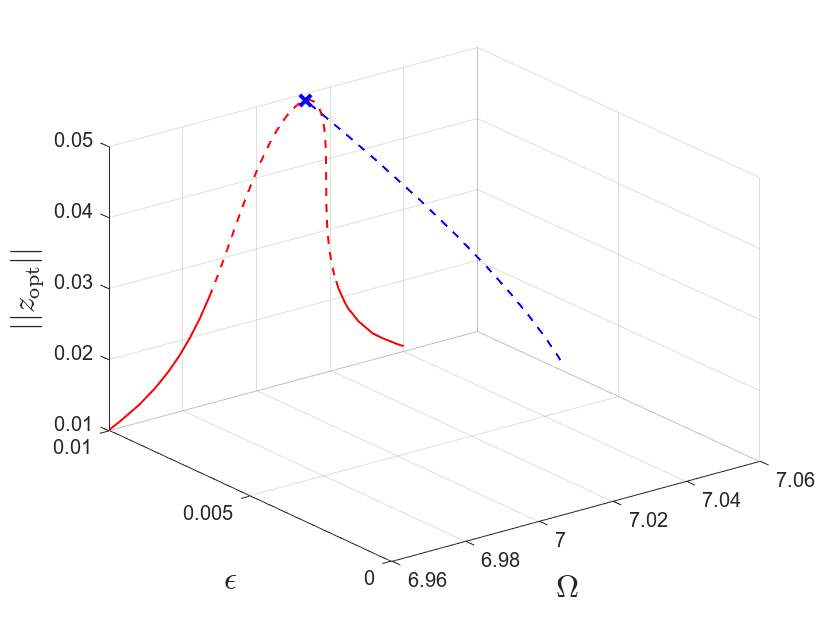

startbc = tic;
optdof = outdof;
set(S.contOptions, 'h0',1e-1,'h_min',1e-3,'h_max',5, 'PtMX', 250);  % continuation setting
epsRange = [0.001 1]*epsilon;
parRange = {freqRange,epsRange};
set(S.FRCOptions,'DBCobjnorm','l2','DBCstepFactor', [10 100]);
set(S.FRSOptions, 'calFRS', true);
S.extract_ridges_trenches('bcssm-top',masterModes,order,mFreq,parRange,outdof,optdof);

We observed that the response amplitude at $\epsilon\to0$ is not zero. This indicates the existence of isola. In order to obtain another branch of solution, we start with a solution with smaller forcing amplitude.

(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     1
     8     2
     0     6
     1     7
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i

sigma_out = 304
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i

sigma_in = 304
Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation

 Second order SSM computation 

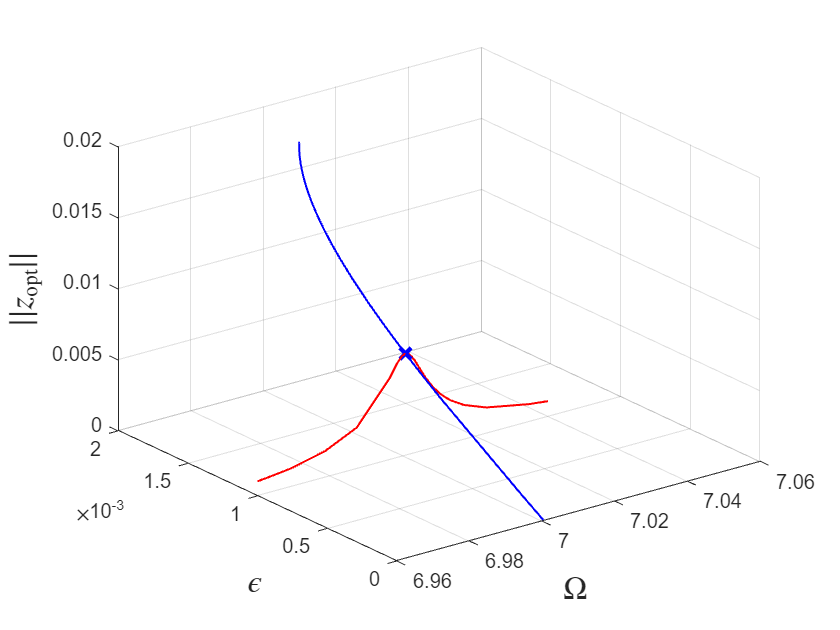

p0 = [6.96 0.1*epsilon]';
z0 = [1e-3 0]';
set(S.contOptions, 'h0',1e-3,'h_min',1e-3,'h_max',5, 'PtMX', 250);  % continuation setting
S.extract_ridges_trenches('bcssm-bot',masterModes,order,mFreq,parRange,outdof,optdof,{p0,z0});

We observed that the last continuation run got stuck at $\epsilon=0.0018020=:\epsilon_s$, where originall variables barely change while Lagrange multipliers change. This indicates the occurance of simple bifurcation. Specifically, when $\epsilon\to\epsilon_s$, the local minimum of the isola merges with the local maximum of the main FRC and the continuation cannot cross this cirtical point. In particular, the design variables are nearly not changed while the lagrange multipliers change linearly. This phenomenon is related to the simple bifurcation as follows

To see that, let $g(x,\omega,\epsilon)=0$ be the curve of fixed points, and  $A=x$ be the optimization objective. The adjoint equations are given by


$$\eta_A+g_x\lambda=0,\quad \eta_\epsilon+g_\epsilon\lambda=0,\quad \eta_\Omega+g_\Omega\lambda=0.$$


At simple bifurcation, we have

$g_x=g_\Omega=0,\quad g_\epsilon\neq0$.

At the backbone curve, we have


$$\eta_A=1,\quad \eta_\Omega=0$$


it follows that the third equation $\eta_\Omega+g_\Omega\lambda=0$ is automatically satisfied, while the first equation implies that $\lambda\to\infty$ when $g_x\to0$ and the second equation further gives $\eta_\epsilon\to\infty$, which explains the phenomenon we obeserved.

Now we plot the results at the same figure

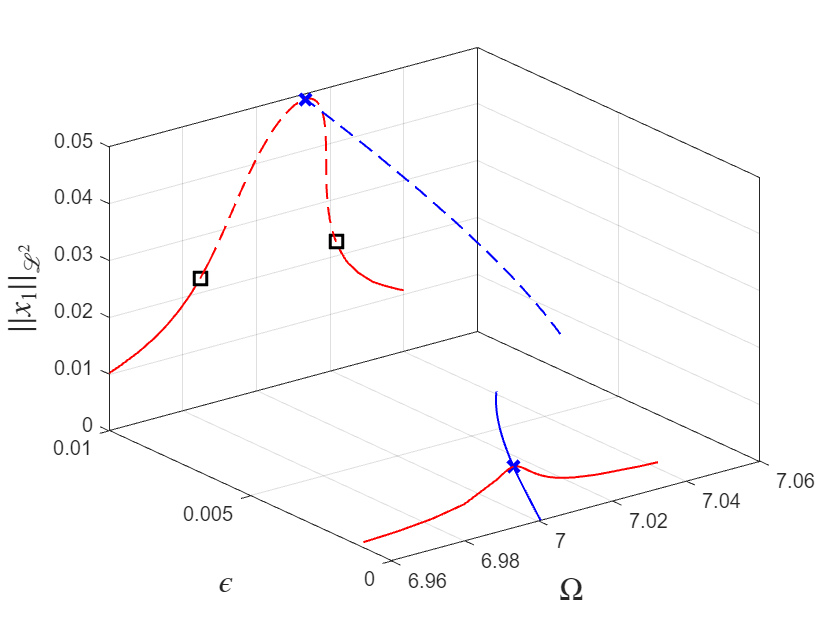

thm = struct( 'special', {{'SN', 'HB' 'BP'}});
thm.SN = {'LineStyle', 'none', 'LineWidth', 2, ...
  'Color', 'cyan', 'Marker', 'o', 'MarkerSize', 8, 'MarkerEdgeColor', ...
  'cyan', 'MarkerFaceColor', 'white'};
thm.HB = {'LineStyle', 'none', 'LineWidth', 2, ...
  'Color', 'black', 'Marker', 's', 'MarkerSize', 8, 'MarkerEdgeColor', ...
  'black', 'MarkerFaceColor', 'white'};
thm.lspec = {{'r-'  'LineWidth'  [1]},{'r--'  'LineWidth'  [1]}};
figure;
% FRCs
coco_plot_bd(thm,'bcssm-top.freq.frc','om','eps','obj'); hold on
coco_plot_bd(thm,'bcssm-bot.freq.frc','om','eps','obj'); hold on
% Dambed backbone curves
coco_plot_bd('bcssm-top.freq.bc1','om','eps','obj'); 
coco_plot_bd('bcssm-bot.freq.bc1','om','eps','obj'); 
xlabel('$\Omega$','Interpreter',"latex",'FontSize',16);
ylabel('$\epsilon$','Interpreter',"latex",'FontSize',16);
zlabel('$||x_1||_{\mathcal{L}^2}$','Interpreter',"latex",'FontSize',16);
grid on;
box on

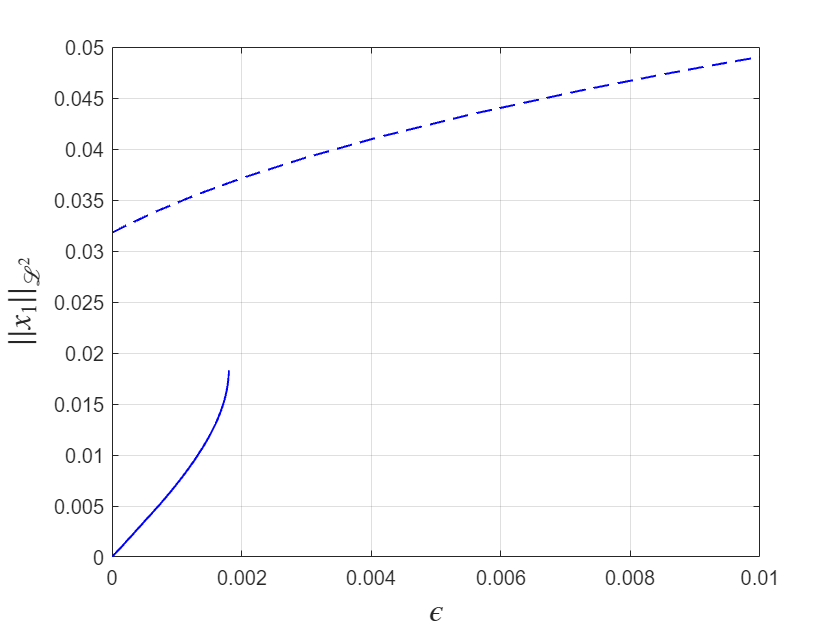

dbcplot = gcf;
figure;
coco_plot_bd('bcssm-top.freq.bc1','eps','obj'); hold on
coco_plot_bd('bcssm-bot.freq.bc1','eps','obj'); 
xlabel('$\epsilon$','Interpreter',"latex",'FontSize',16);
ylabel('$||x_1||_{\mathcal{L}^2}$','Interpreter',"latex",'FontSize',16);
grid on;

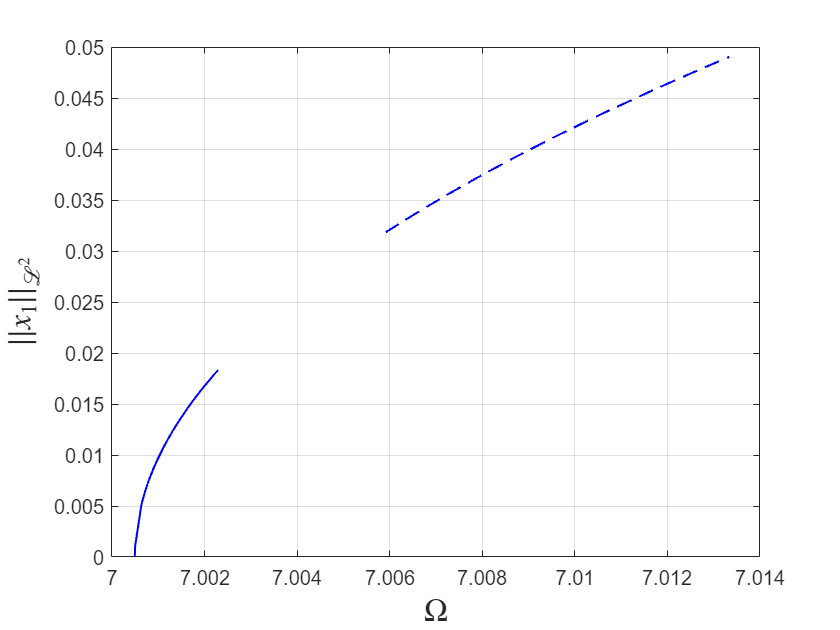

dbcepsplot = gcf;
figure;
coco_plot_bd('bcssm-top.freq.bc1','om','obj'); hold on
coco_plot_bd('bcssm-bot.freq.bc1','om','obj'); 
xlabel('$\Omega$','Interpreter',"latex",'FontSize',16);
ylabel('$||x_1||_{\mathcal{L}^2}$','Interpreter',"latex",'FontSize',16);
grid on;

dbcomplot = gcf;

The results above are maixmum solutions. For an isola, there exists a local minium as well. The algorithm here also supports the computation of minimum solutions. So we perform another computation with a solution on the isola as initial point.

(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     1
     8     2
     0     6
     1     7
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i

sigma_out = 304
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i

sigma_in = 304
Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation

 Second order SSM computation 

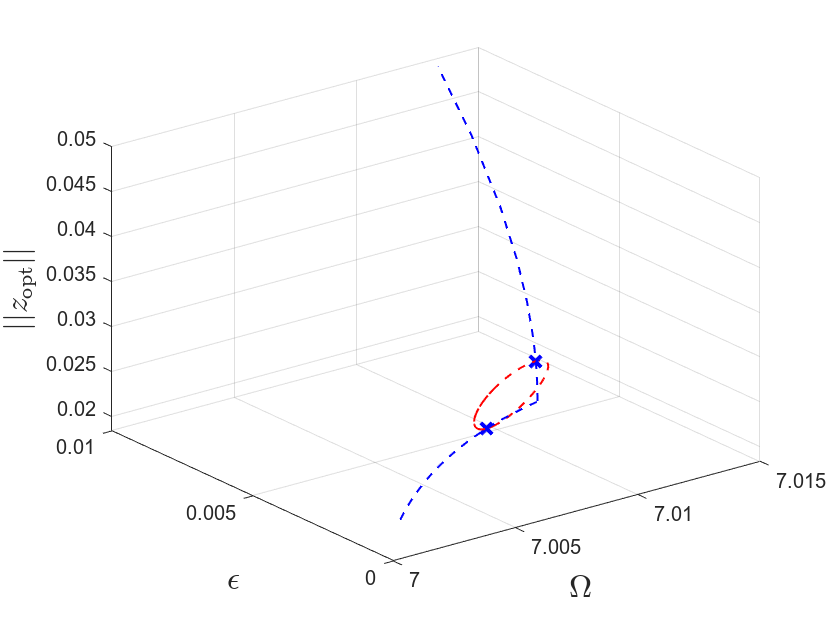

sol = ep_read_solution('bcssm-top.freq.bc1',3);
pso = [7.006 0.000855]';
set(S.contOptions, 'PtMX', [30 65]);
set(S.FRCOptions,'DBCstepFactor', [10 1000]);
% set(S.contOptions, 'h0',1e-3,'h_min',1e-3,'h_max',5, 'PtMX', 250, 'MaxRes', 0.1);  % continuation setting
S.extract_ridges_trenches('bcssm-mid',masterModes,order,mFreq,parRange,outdof,optdof,{pso,sol.x});

timings.epbc = toc(startbc);

Now we plot the results of the minimum branch along with the maximum solutions

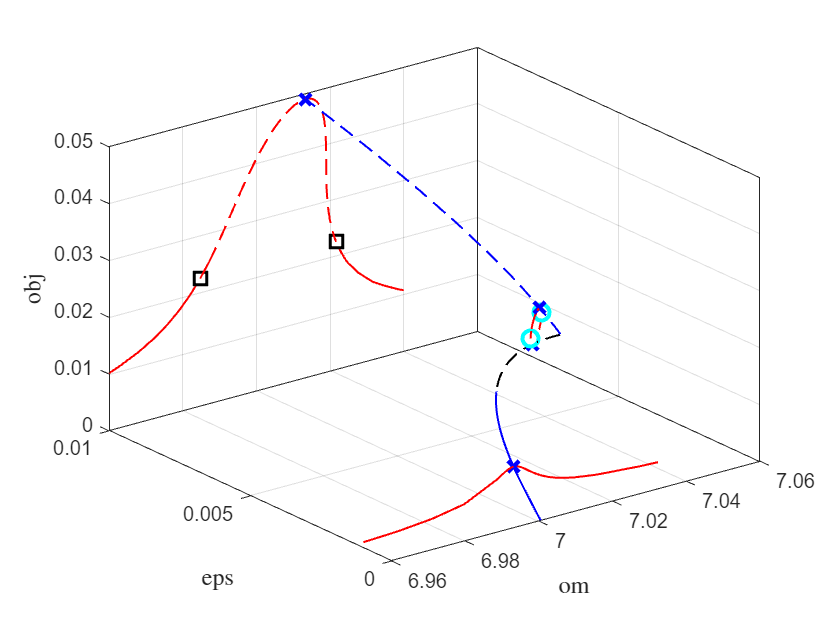

thm2.lspec = {{'k-'  'LineWidth'  [1]},{'k--'  'LineWidth'  [1]}};
figure(dbcplot); hold on
coco_plot_bd(thm,'bcssm-mid.freq.frc','om','eps','obj'); 
xlabel('$\Omega$','Interpreter',"latex",'FontSize',16);
ylabel('$\epsilon$','Interpreter',"latex",'FontSize',16);
zlabel('$||x_1||_{\mathcal{L}^2}$','Interpreter',"latex",'FontSize',16);
grid on;
box on
% Dambed backbone curves
coco_plot_bd(thm2,'bcssm-mid.freq.bc1','om','eps','obj'); 

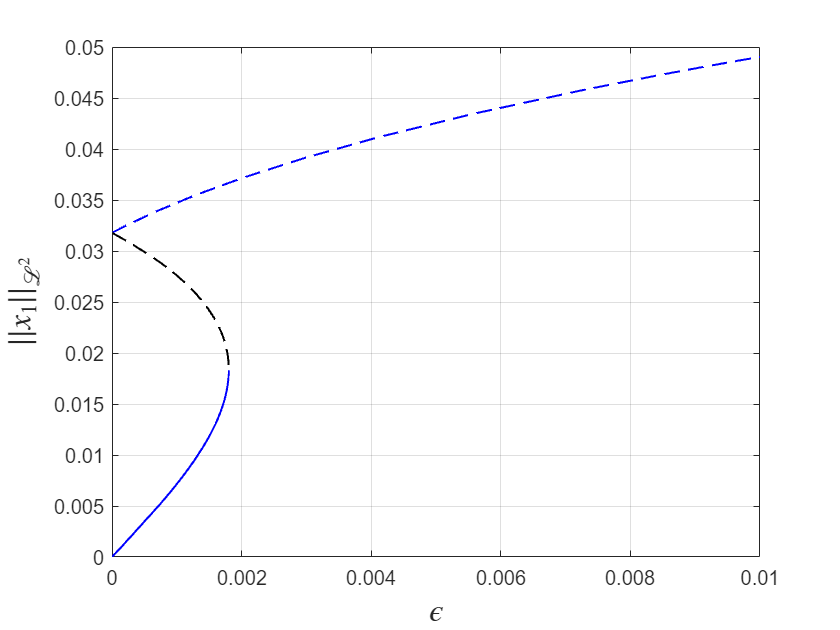

figure(dbcepsplot); hold on
coco_plot_bd(thm2,'bcssm-mid.freq.bc1','eps','obj'); 
xlabel('$\epsilon$','Interpreter',"latex",'FontSize',16);
ylabel('$||x_1||_{\mathcal{L}^2}$','Interpreter',"latex",'FontSize',16);
grid on;

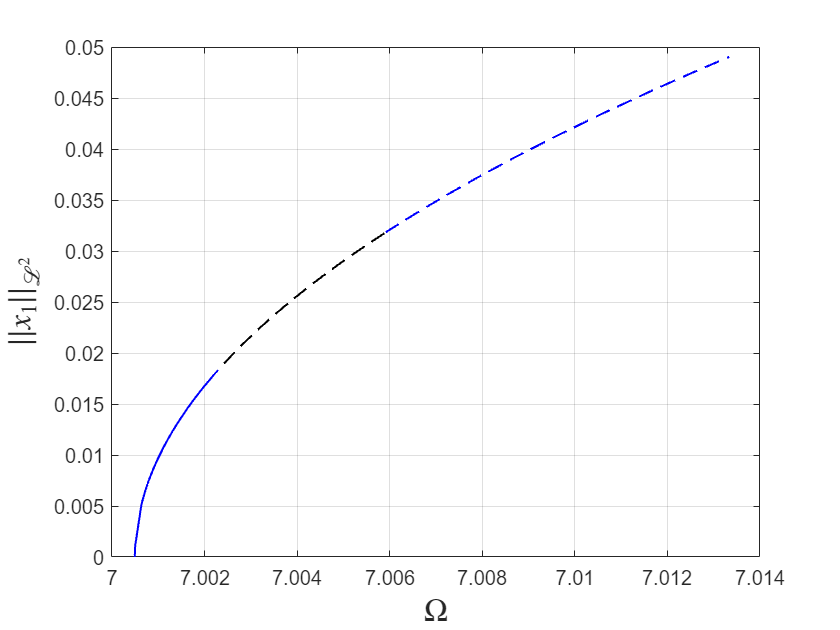

figure(dbcomplot);
coco_plot_bd(thm2,'bcssm-mid.freq.bc1','om','obj'); hold on
xlabel('$\Omega$','Interpreter',"latex",'FontSize',16);
ylabel('$||x_1||_{\mathcal{L}^2}$','Interpreter',"latex",'FontSize',16);
grid on;

We also plot the backbone curve in $(\Omega,||x||)$ plane along with the backbone curve predicted based on the decay on SSM.

(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     1
     8     2
     0     6
     1     7
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i

sigma_out = 304
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i

sigma_in = 304
Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation

 Second order SSM computation 

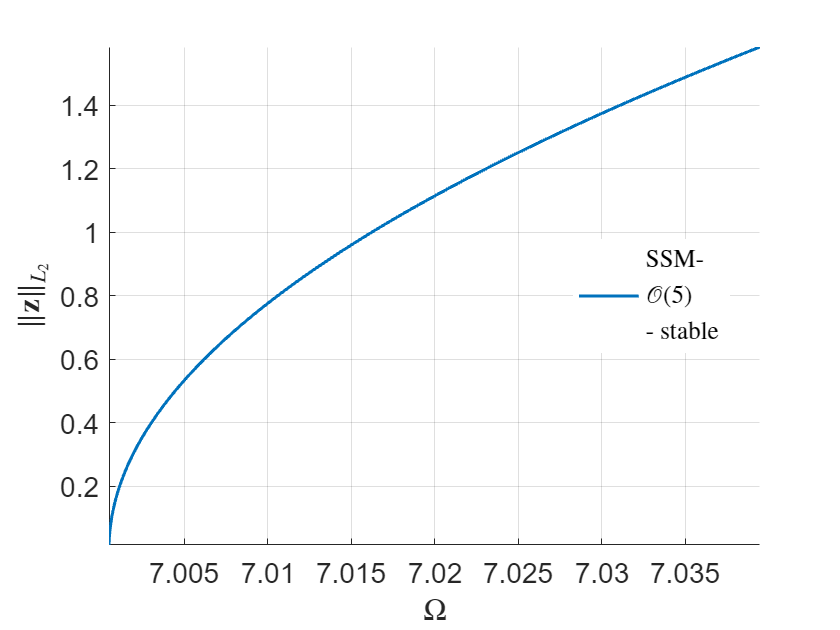

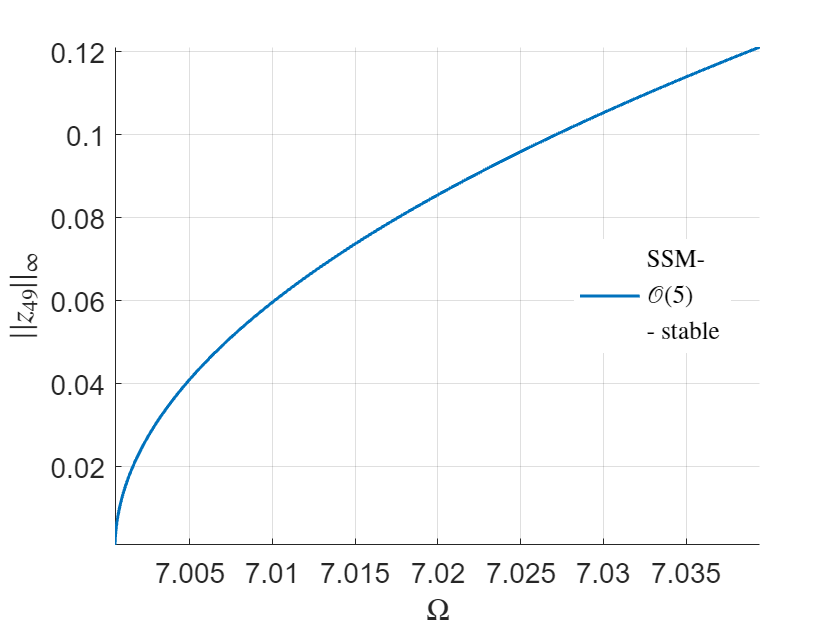

Total time spent on backbone curve computation = 00:00:00


set(S.FRCOptions,'outdof',outdof);
bc_ssm = S.extract_backbone(masterModes,freqRange,order);

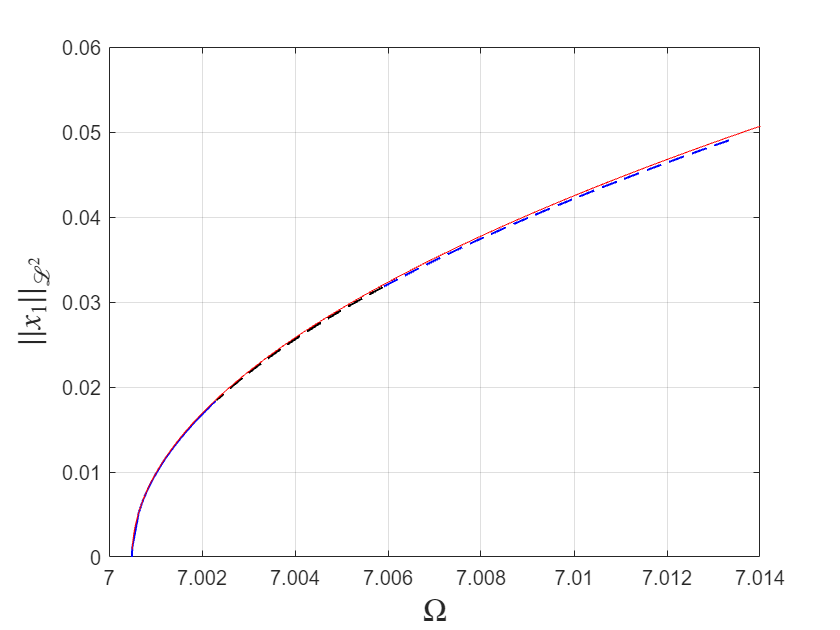

figure(dbcomplot);
coco_plot_bd('bcssm-top.freq.bc1','om','obj'); hold on
coco_plot_bd('bcssm-bot.freq.bc1','om','obj'); 
plot([bc_ssm.Omega],[bc_ssm.ZoutNorm],'r-');
xlabel('$\Omega$','Interpreter',"latex",'FontSize',16);
ylabel('$||x_1||_{\mathcal{L}^2}$','Interpreter',"latex",'FontSize',16);
grid on;
xlim([7 7.014]); ylim([0 0.06])

For visualization purpose, we calcuate a few more forced response curves with varied forcing amplitude $\epsilon$.

(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     1
     8     2
     0     6
     1     7
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 +43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i
  -0.2406 -43.8707i

sigma_out = 304
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 + 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i
  -0.0062 - 7.0005i

sigma_in = 304
Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation

 Second order SSM computation 

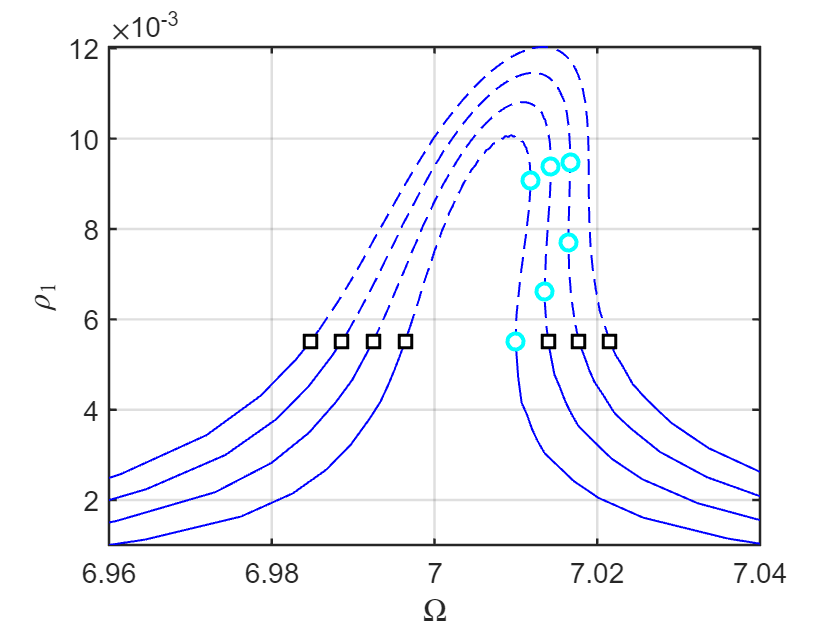

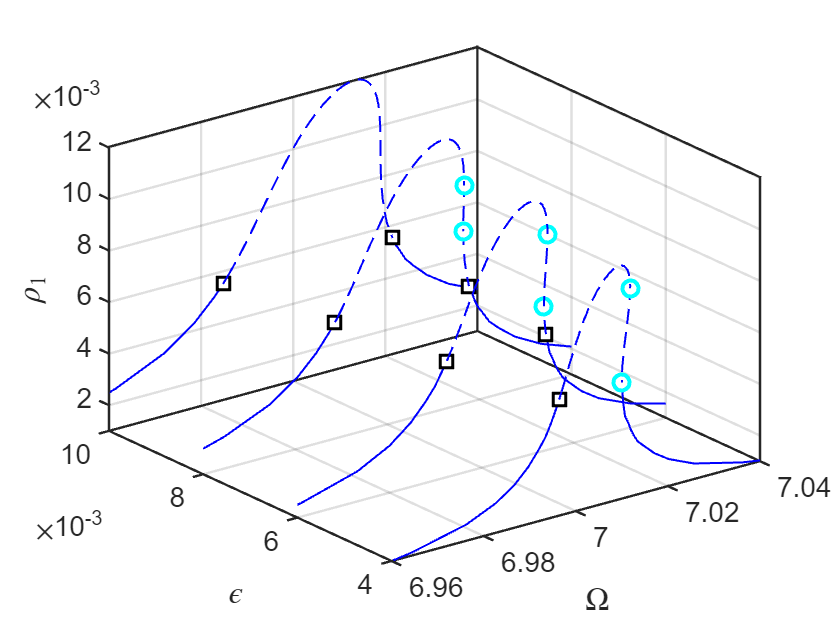

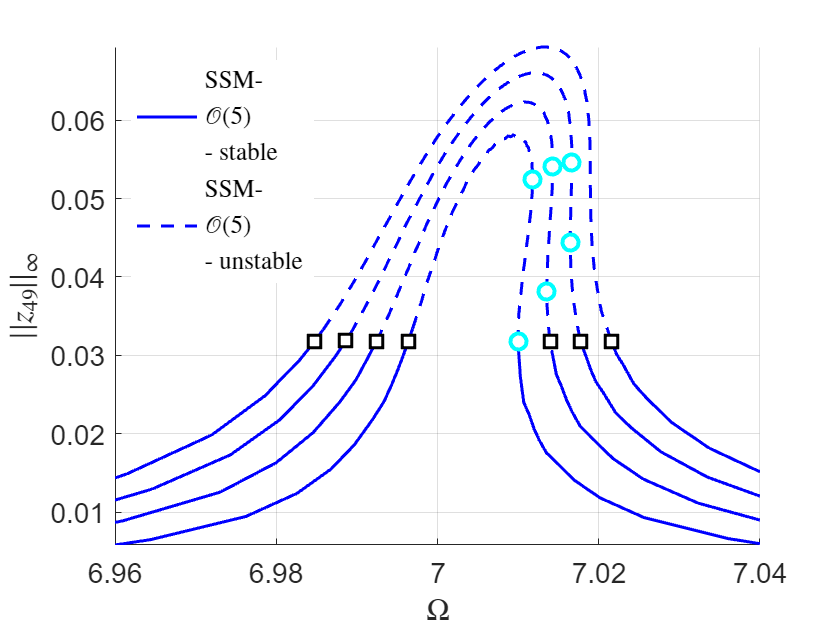

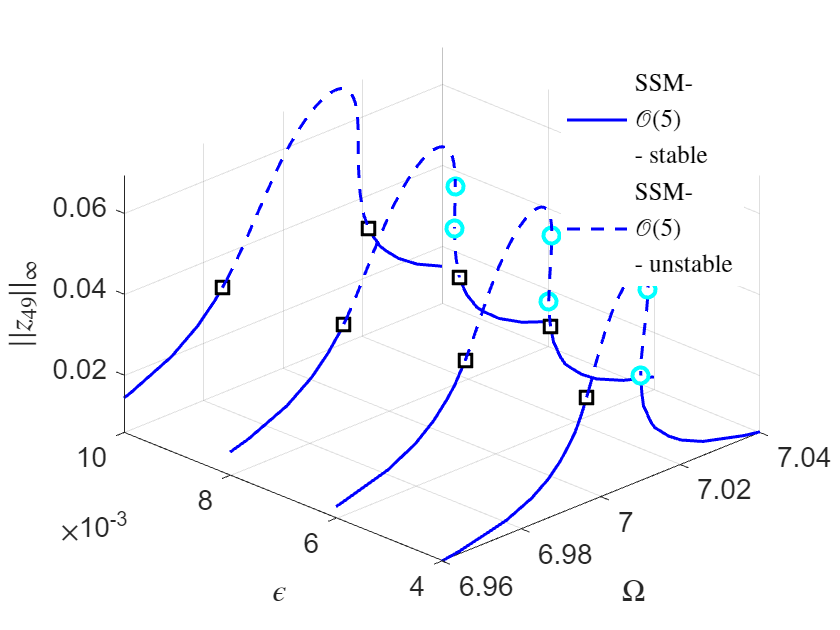

epssamps = [0.004 0.006 0.008 0.01];
FRCmain = S.SSM_epSweeps('main',masterModes,order,mFreq,epssamps,freqRange,outdof);

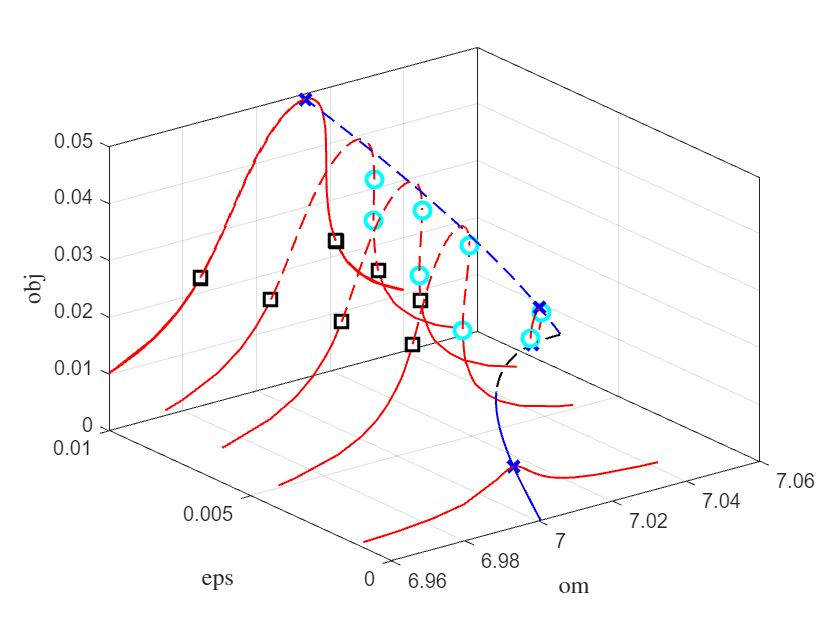

ST = cell(2,1);
ST{1} = {'r--','LineWidth',1.0}; % unstable
ST{2} = {'r-','LineWidth',1.0};  % stable
FRCom = FRCmain.FRCom;
figure(dbcplot); hold on
for k=1:numel(epssamps)
    om = FRCom{k}.om;
    epsf = FRCom{k}.ep;
    Anorm = FRCom{k}.ZoutNorm_frc;
    stab = FRCom{k}.st;
    plot3_stab_lines(om,epsf,Anorm,stab,ST);
    % plot special points
    SNidx = FRCom{k}.SNidx;
    SNfig = plot3(om(SNidx),epsf(SNidx),Anorm(SNidx),thm.SN{:});
    set(get(get(SNfig,'Annotation'),'LegendInformation'),...
        'IconDisplayStyle','off');
    HBidx = FRCom{k}.HBidx;
    HBfig = plot3(om(HBidx),epsf(HBidx),Anorm(HBidx),thm.HB{:});
    set(get(get(HBfig,'Annotation'),'LegendInformation'),...
        'IconDisplayStyle','off');        
end